% Definir los valores de los componentes
R=1000; % Valor de la resistencia en ohmios
C=100e-9; % Valor de la capacitancia en faradios

% Declarar variables simbólicas s y t para uso en la función de transferencia
syms s t
% Definir la función de transferencia H(s) en el dominio de Laplace
funcion = 1/(R*C*s + 1);

% Mostrar la función de transferencia en una forma legible
pretty(funcion);

    1
---------
  s
----- + 1
10000



% Calcular la inversa de Laplace para obtener la respuesta en el dominio del tiempo
inversa=ilaplace(funcion);
% Mostrar la respuesta en el dominio del tiempo en una forma legible
pretty(inversa);

exp(-10000 t) 10000



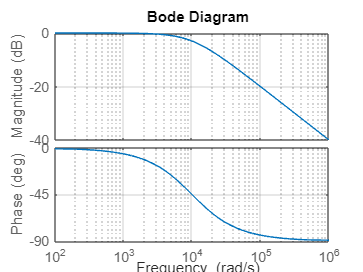

% Crear una representación de la función de transferencia en el dominio de Laplace
num = [1];
den = [R*C 1];
otra = tf(num,den);
% Realizar un diagrama de Bode de la función de transferencia y agregar una cuadrícula
bode(otra),grid

% Definir los valores de los componentes
R=1000; % Valor de la resistencia en ohmios
C=10e-9; % Valor de la capacitancia en faradios

% Declarar variables simbólicas s y t para uso en la función de transferencia
syms s t
% Definir la función de transferencia H(s) en el dominio de Laplace
funcion = 1/(R*C*s + 1);

% Mostrar la función de transferencia en una forma legible
pretty(funcion);

     1
----------
   s
------ + 1
100000



% Calcular la inversa de Laplace para obtener la respuesta en el dominio del tiempo
inversa=ilaplace(funcion);
% Mostrar la respuesta en el dominio del tiempo en una forma legible
pretty(inversa);

exp(-100000 t) 100000



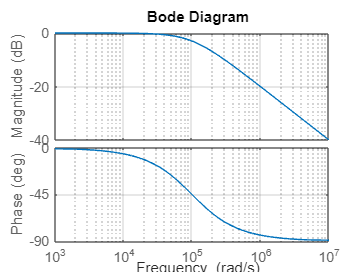

% Crear una representación de la función de transferencia en el dominio de Laplace
num = [1];
den = [R*C 1];
otra = tf(num,den);
% Realizar un diagrama de Bode de la función de transferencia y agregar una cuadrícula
bode(otra),grid

% Definir los valores de los componentes
% Resistencias que determinan la amplificación del amplificador operacional
R1=1000;
R2=2000;

R=1000; % Valor de la resistencia en ohmios
C=100e-9; % Valor de la capacitancia en faradios

Gana=(R2/R1)+1 % Ganancia amplificador no inversor

Gana = 3


% Declarar variables simbólicas s y t para uso en la función de transferencia
syms s t
% Definir la función de transferencia H(s) en el dominio de Laplace
funcion=1/(R*C*s + 1);
activo=Gana*funcion % Filtro activo, multiplica la ganancia por la función de transferencia

$$activo = \frac{3}{\frac{s}{10000}+1}$$

% Mostrar la función de transferencia en una forma legible
pretty(activo);

    3
---------
  s
----- + 1
10000



% Calcular la inversa de Laplace para obtener la respuesta en el dominio del tiempo
inversa=ilaplace(activo);
% Mostrar la respuesta en el dominio del tiempo en una forma legible
pretty(inversa);

exp(-10000 t) 30000



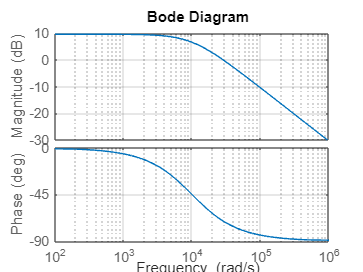

% Crear una representación de la función de transferencia en el dominio de Laplace
num = [Gana];
den = [R*C 1];
otra = tf(num,den);
% Realizar un diagrama de Bode de la función de transferencia y agregar una cuadrícula
bode(otra),grid

% Definir los valores de los componentes
% Resistencias que determinan la amplificación del amplificador operacional
R1=1000;
R2=2000;

R=1000; % Valor de la resistencia en ohmios
C=10e-9; % Valor de la capacitancia en faradios

Gana=(R2/R1)+1 % Ganancia amplificador no inversor

Gana = 3


% Declarar variables simbólicas s y t para uso en la función de transferencia
syms s t
% Definir la función de transferencia H(s) en el dominio de Laplace
funcion=1/(R*C*s + 1);
activo=Gana*funcion % Filtro activo, multiplica la ganancia por la función de transferencia

$$activo = \frac{3}{\frac{s}{100000}+1}$$

% Mostrar la función de transferencia en una forma legible
pretty(activo);

     3
----------
   s
------ + 1
100000



% Calcular la inversa de Laplace para obtener la respuesta en el dominio del tiempo
inversa=ilaplace(activo);
% Mostrar la respuesta en el dominio del tiempo en una forma legible
pretty(inversa);

exp(-100000 t) 300000



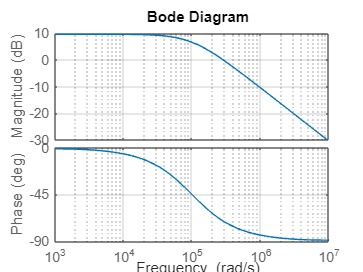

% Crear una representación de la función de transferencia en el dominio de Laplace
num = [Gana];
den = [R*C 1];
otra = tf(num,den);
% Realizar un diagrama de Bode de la función de transferencia y agregar una cuadrícula
bode(otra),grid